# Lab 2 DC Motor 

## Real System Step Response

The following Figure 1-1 shows the step repsonse of the DC Motor with position closed-loop feedback collected during lab.

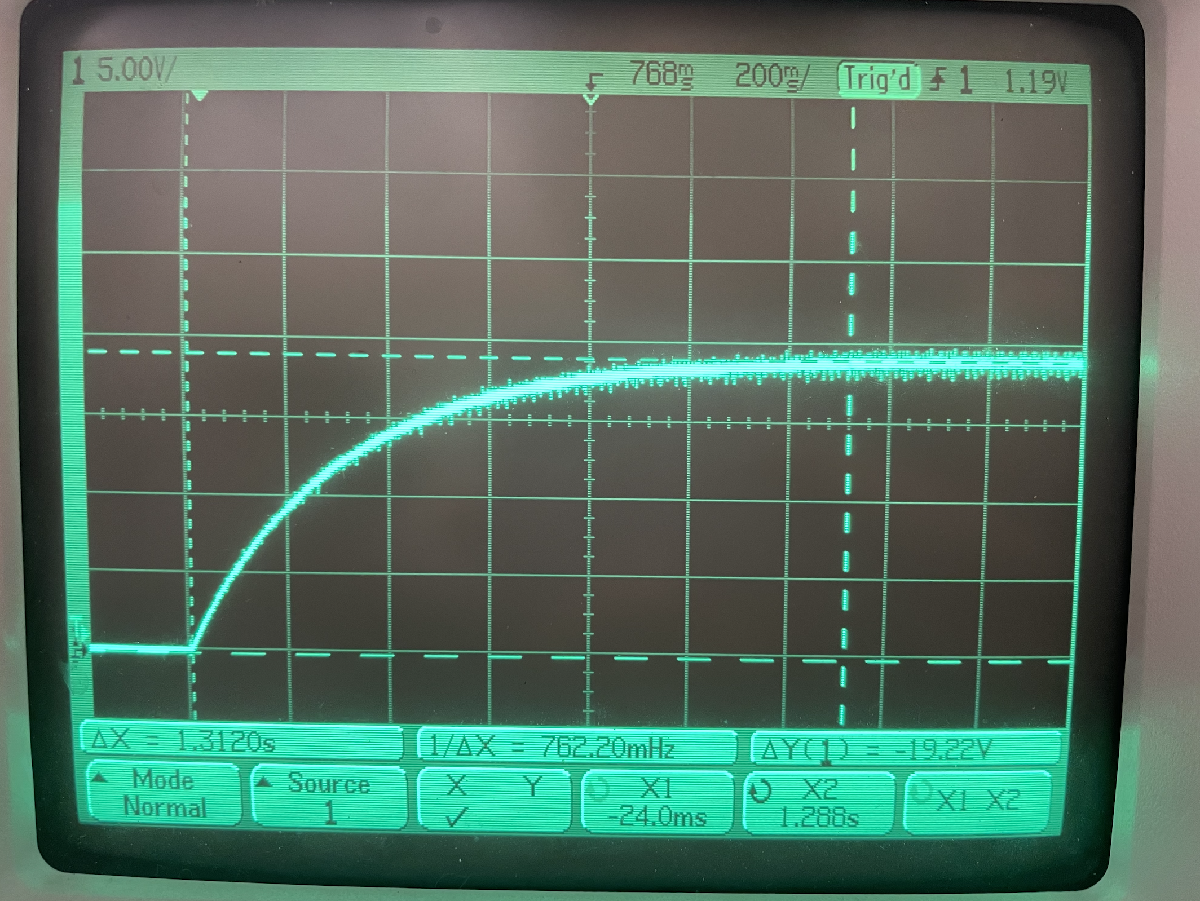

**Figure 1-1 **Step Response of DC Motor with Position Closed-Loop Feedback

The gain is 19.22 Volts. 

Tau_Location = 0.63*19.22

Tau_Location = 12.1086

The location of the time constant, Tau, sits at 63% of the gain. This is at 12.1086 Volts. By observation, the time response sits at about 0.5 seconds into the step response curve. 

## Simulink Models

### Open Loop Step Responses

sim_OL = sim('Ex2Week1Simupdate.slx');

The constant, Km,lin, was determined for the linear model by making an estimate of the "average" slope of the wm vs VA data collected during lab. The linear model uses Km,lin as the motor constant. 

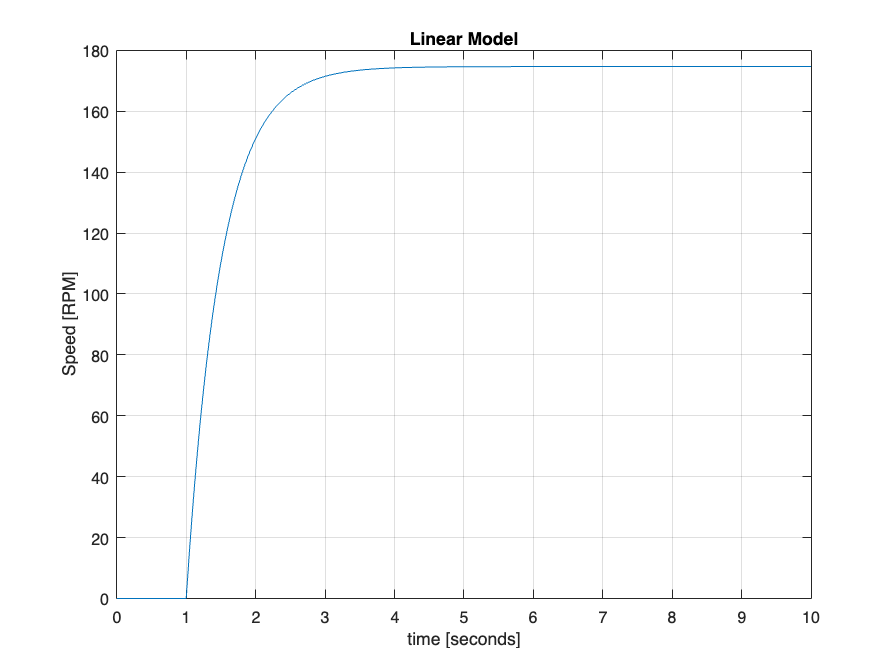

plot(sim_OL.tout,sim_OL.Linear)
title("Linear Model")
ylabel("Speed [RPM]")
xlabel("time [seconds]")
grid on

The constant Km for the nonlinear model was determined by finding the slope of the wm vs VA data  outside of the deadband area. 

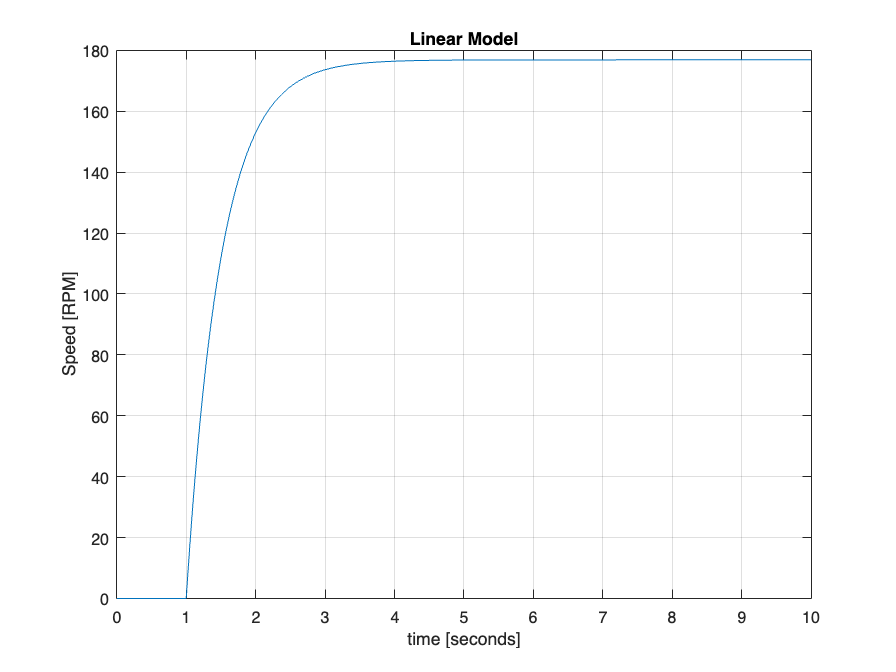

% Km=0.194
plot(sim_OL.tout,sim_OL.nonlinear)
title("Non-Linear Model")
ylabel("Speed [RPM]")
xlabel("time [seconds]")
grid on

### Closed Loop Step Responses 

The previous open loop simulink model was modified to represent a closed loop model. This was done by adding an output potentiometer in a feedback path that connected the output position theta to the correct input of the op-amp summing amplifier. 

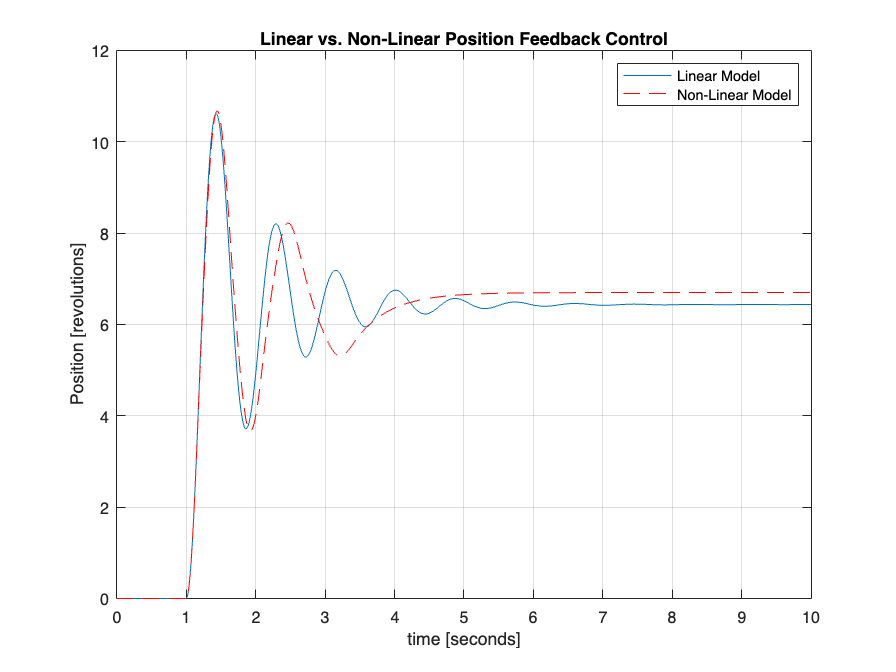

figure()
plot(sim_OL.tout,sim_OL.linfeedback)
hold on
plot(sim_OL.tout,sim_OL.nonlinfeedback,"r--")
title("Linear vs. Non-Linear Position Feedback Control")
ylabel("Position [revolutions]")
xlabel("time [seconds]")
legend("Linear Model", "Non-Linear Model")
grid on
hold off